Astart = zeros([5 5 3]);
Adir = zeros([5 5 3]);
Bstart = zeros([5 5 3]);
Bdir = zeros([5 5 3]);

for y = 1:5
    for x = 1:5
        Astart(y, x, :) = [0.0 0.0 0.0];
        Adir(y, x, :) = [1.0 1.0 0.0];
        Bstart(y, x, :) = [0.5 0.0 0.5];
        Bdir(y, x, :) = [0.0 1.0 0.0];
    end
end

% Plotting only.
A = Astart(1, 1, :) + Adir(1, 1, :) .* (0:1)';
B = Bstart(1, 1, :) + Bdir(1, 1, :) .* (0:1)';

Astart = gpuArray(Astart);
Adir = gpuArray(Adir);
Bstart = gpuArray(Bstart);
Bdir = gpuArray(Bdir);

[Cstart, Cend] = lineintersect(Astart, Adir, Bstart, Bdir);

Cstart = gather(Cstart);
Cend = gather(Cend);

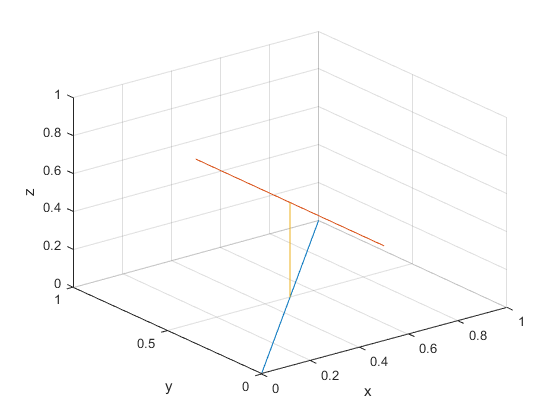

Cdir = Cend - Cstart;
C = Cstart(1, 1, :) + Cdir(1, 1, :) .* (0:1)';

plot3(A(:, 1), A(:, 2), A(:, 3), ...
    B(:, 1), B(:, 2), B(:, 3), ...
    C(:, 1), C(:, 2), C(:, 3));

xlabel('x');
ylabel('y');
zlabel('z');
xlim([0.0 1.0]) ;
ylim([0.0 1.0]);
zlim([0.0 1.0]);
grid on;


% Cstart on A, Cend on B.

function [Cstart, Cend] = lineintersect(Astart, Adir, Bstart, Bdir)
    [Y, X, ~] = size(Astart);
    
    Cdir = cross(Adir, Bdir, 3);
    bAll = Bstart - Astart;
    
    MAll = zeros([Y X 3 3]);
    MAll(:, :, :, 1) = Adir;
    MAll(:, :, :, 2) = Cdir;
    MAll(:, :, :, 3) = -Bdir;
    
    LAll = zeros([Y X 3 3]);
    UAll = zeros([Y X 3 3]);
    PAll = zeros([Y X 3 3]);
    
    % To-Do: Find way to parallelize lu().
    for y = 1:Y
        for x = 1:X
            [L, U, P] = lu(squeeze(MAll(y, x, :, :)));
            LAll(y, x, :, :) = L;
            UAll(y, x, :, :) = U;
            PAll(y, x, :, :) = P;
        end
    end
    
    sAll = solveluparallel(LAll, UAll, PAll, bAll);
            
    Cstart = Astart + squeeze(sAll(:, :, 1)) .* Adir;
    %Cend = Bstart + squeeze(sAll(:, :, 3) .* Bdir;
    Cend = Cstart + squeeze(sAll(:, :, 2)) .* Cdir;
end